%load('runme_data','M','B')

d65 = B;

spd_target_orig = d65;

% spd_0 = ls.spd_0';
% spd_max = ls.spd_all' - spd_0;
mea_max = measure_white(ol,cs);

Yxy =    51.5620    0.3751    0.4087


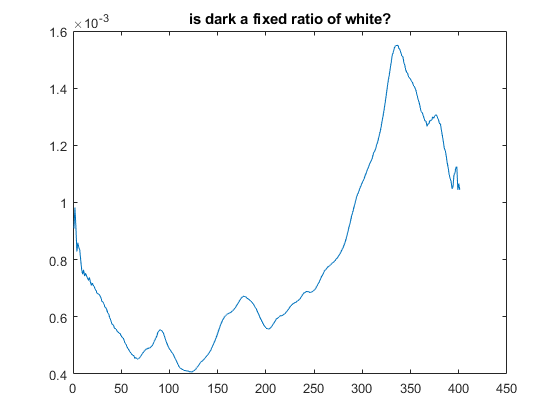


spd_0 = mea_0.amplitude';
spd_max = mea_max.amplitude';

ratio_0 = spd_0 ./ spd_max;

clf
plot(ratio_0)
title('is dark a fixed ratio of white?')

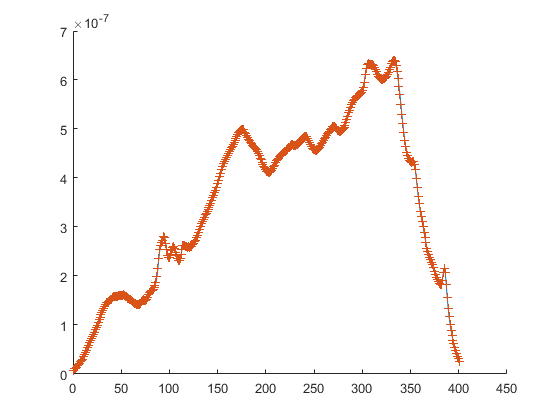


clf
hold on
plot(spd_0)
plot(spd_max .*  ratio_0,'+')


sc = 0.1

sc = 0.1000

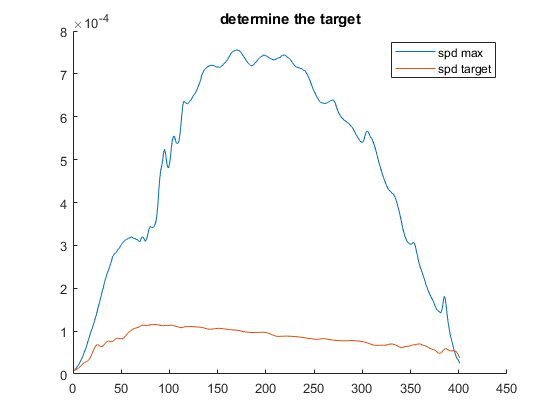

spd_target = spd_target_orig .* sc;
clf
hold on
plot(spd_max)
plot(spd_target)
legend('spd max','spd target')
title('determine the target')

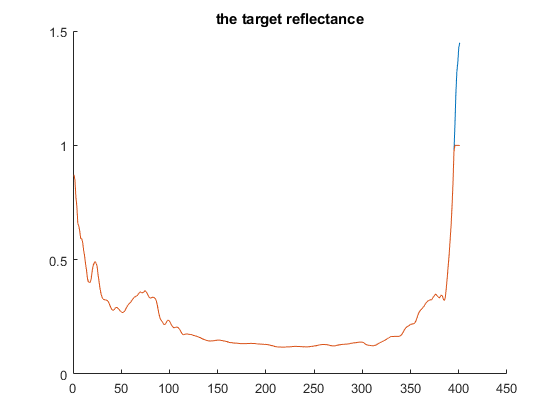

ref_target_orig = (spd_target - spd_0) ./ (spd_max - spd_0);
ref_target = min(1,ref_target_orig);

clf
hold on
plot(ref_target_orig)
plot(ref_target)
title('the target reflectance')

ref_m = ls.reflectance';

vec_a_orig = R_callRsolver1024(ref_m,ref_target);

ans = 'Solving M * A = B with R...'

ans = 0

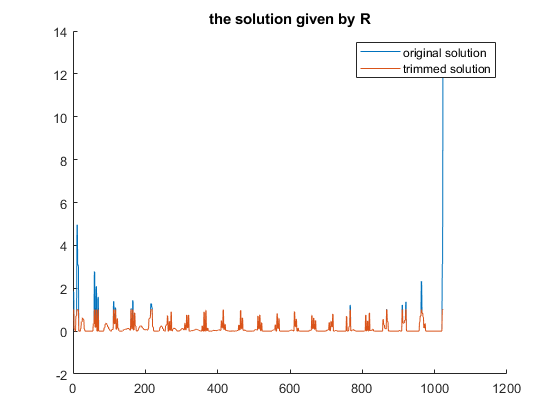

vec_a = vec_a_orig;
vec_a = min(1,vec_a);
vec_a = max(0,vec_a);

clf
hold on
plot(vec_a_orig)
plot(vec_a)
legend('original solution','trimmed solution')
title('the solution given by R')

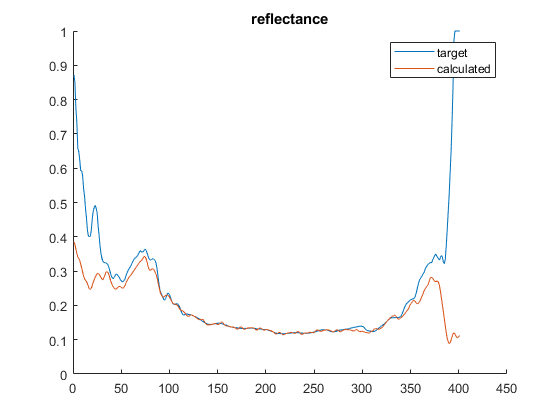

clf
hold on
plot(ref_target)
ref = ref_m * vec_a;
plot(ref)
legend('target','calculated')
title('reflectance')

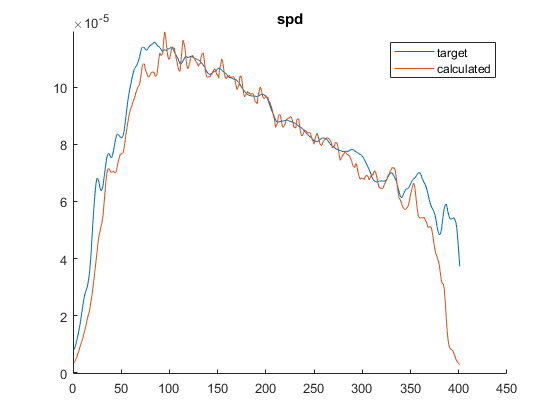

clf
hold on
plot(spd_target)
spd = spd_max .* ref + spd_0;
plot(spd)
legend('target','calculated')
title('spd')

the vec needs to be doubled to match

spec_predicted = ls.predict_vec_max(vec_a,spd_max);

ol.setColumn1024Gamma(vec_a)
mea = cs.measure;

Yxy =     4.4403    0.3174    0.3376


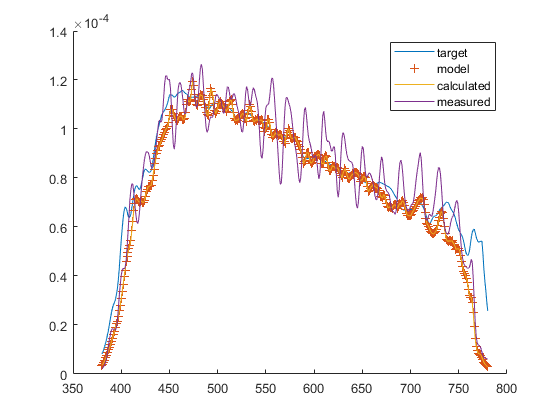

t = mea.amplitude;

clf
hold on

spd_target_ref = spd_max .* ref_target + spd_0;
plot(380:780,spd_target_ref)

plot(380:780,spec_predicted,'+')

spd = spd_max .* ref + spd_0;
plot(380:780,spd)

%mea.plot
plot(380:780,t/0.6)
legend('target','model','calculated','measured')

%clf
%plot(t,)

ol.setColumn1024(LightSim.multiple_peaks(1:1024))
mea_all = cs.measure;

Yxy =    52.8380    0.3752    0.4089


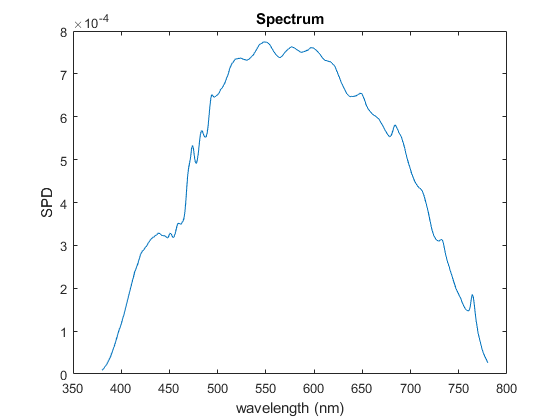

clf
mea_all.plot

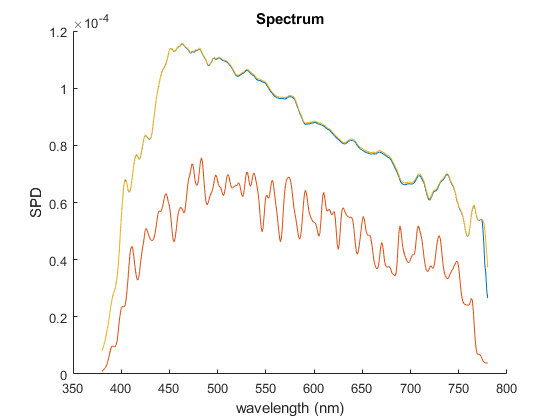

clf
hold on
plot(380:780,spd_max .* ref_target)
mea.plot
plot(380:780,spd_target)

%plot(380:780,spd_max)
%mea_all.plot

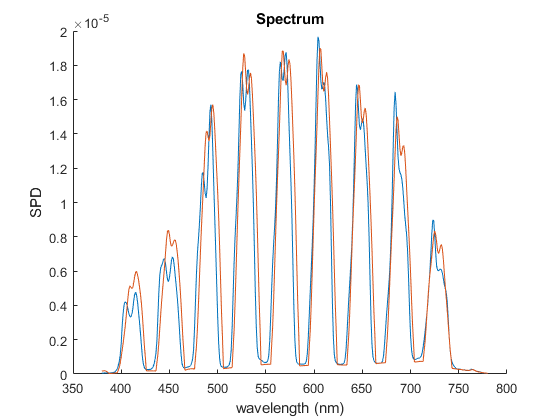

c_range = [1:100:1000];

ol.setColumn1024(LightSim.multiple_peaks(c_range))
mea_500 = cs.measure;

ol.setColumn1024(LightSim.multiple_peaks([1:1024]))
mea_all = cs.measure;

s_pred = ls.predict_by_filter(LightSim.multiple_peaks(c_range));

clf
hold on
t_500 = mea_500.amplitude ./ mea_all.amplitude;
%plot(t_500)
mea_500.plot
plot(380:780,s_pred)

col_g = 435

col_g = 435

col_width = 140;
c_range = [col_g-col_width:col_g+col_width];
x_g = 0.33;
y_g = 0.6;
[100 x_g y_g atan2d(y_g,x_g) (x_g.^2+y_g.^2).^0.5]

ans =   100.0000    0.3300    0.6000   61.1892    0.6848



ol.setColumn1024(LightSim.multiple_peaks(c_range))
Yxy = cs.measure_Yxy

Yxy =    43.4120    0.3350    0.5956   60.6441    0.6833


col_r = 730

col_r = 730

col_width = 150;
c_range = [col_r-col_width:col_r+col_width];
x_r = 0.64;
y_r = 0.30;
[100 x_r y_r atan2d(y_r,x_r) (x_r.^2+y_r.^2).^0.5]

ans =   100.0000    0.6400    0.3000   25.1148    0.7068



ol.setColumn1024(LightSim.multiple_peaks(c_range))
Yxy = cs.measure_Yxy

Yxy =     9.8866    0.6792    0.3200   25.2271    0.7508


return

clf
hold on
mea_500.plot

how wide need to reach max

c_range = 1:1024;
vec = LightSim.multiple_peaks(c_range);
ol.setColumn1024(vec)
mea_max = cs.measure;

Yxy =    53.5860    0.3749    0.4088




width = 25;
wl = 708;
c_range = [wl-width:wl+width];
vec = LightSim.multiple_peaks(c_range);
ol.setColumn1024(vec)
mea = cs.measure;

Yxy =     1.0616    0.7150    0.2812


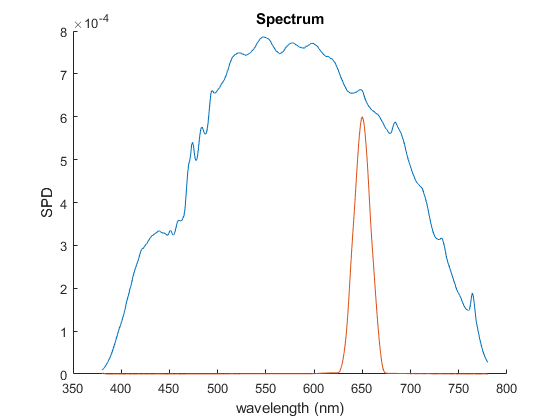

clf
hold on
mea_max.plot
mea.plot

vec8_array = ls.vec_8_spikes;
vec8_sum = sum(vec8_array,1);

ol.setColumn1024(vec8_sum)
mea_8 = cs.measure;

Yxy =    20.5890    0.3816    0.4083


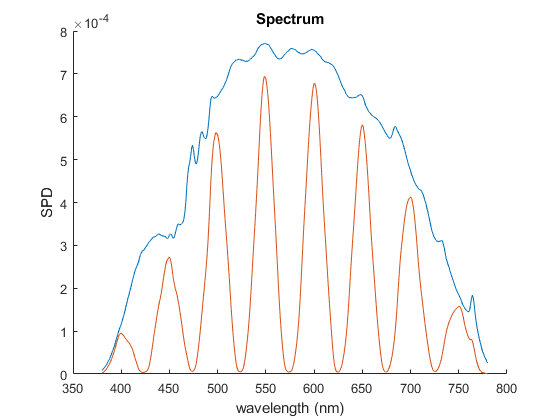


clf
hold on
mea_max.plot
mea_8.plot

i=5;
ol.setColumn1024(vec8_array(i,:))
mea = cs.measure;

Yxy =     6.6957    0.6193    0.3792


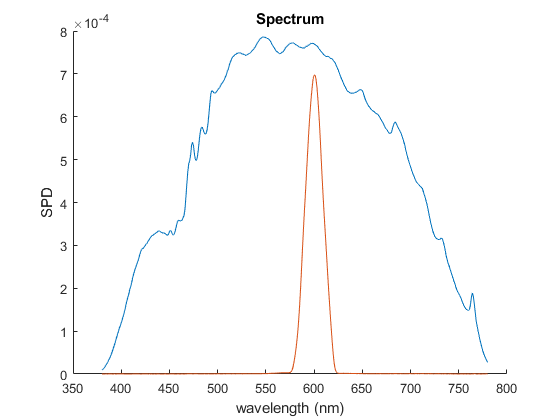

clf
hold on
mea_max.plot
mea.plot

spd_target

spd_target = 	1.0e+-3 *

    0.0204
    0.0223
    0.0255
    0.0287
    0.0325
    0.0364
    0.0413
    0.0461
    0.0520
    0.0578


index_8 = wl_center - 380 + 1;
amp_8_target = spd_target(index_8)';
amp_8_max = mea_8.amplitude(index_8);
ratio_8 = amp_8_target ./ amp_8_max;
ratiovec_8 = interp1(veclut(:,2),veclut(:,1),ratio_8,'spline')

ratiovec_8 =     0.8562    1.0020    0.7427    0.6780    0.6513    0.6598    0.6980    0.9679


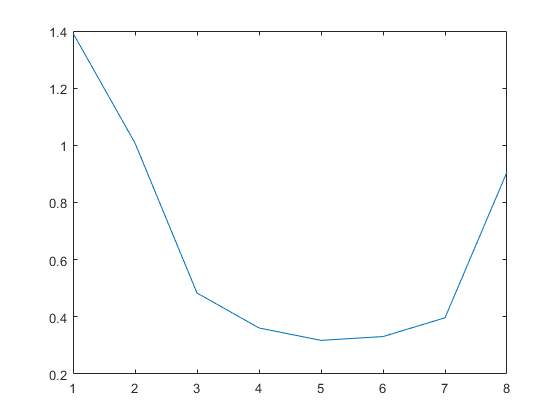

%ratio_8 = [1 1 1 1 1 1 1 1] * 0.8;

clf
plot(ratio_8)


vec = vec8_array' * ratio_8';
ol.setColumn1024(vec)
mea = cs.measure;

Yxy =     7.2211    0.2989    0.3066


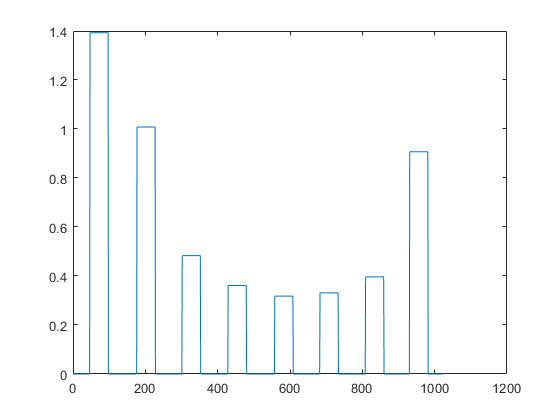

clf
plot(vec)

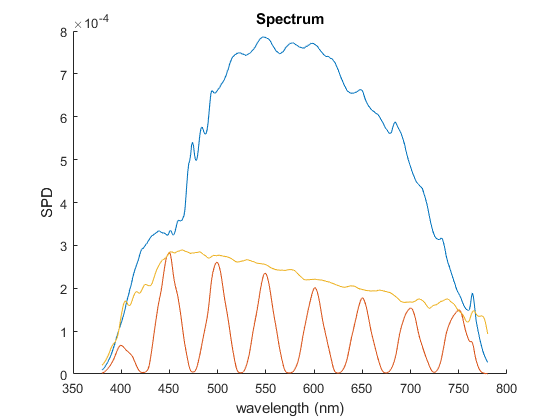


clf
hold on
mea_max.plot
mea.plot
plot(380:780,spd_target)

for i = 1:10
    ratio_8 = [1 1 1 1 1 1 1 1] * i / 10;
    vec = vec8_array' * ratio_8';
    ol.setColumn1024(vec)
    mea = cs.measure;
    meascale{i} = mea;
end

Yxy =     0.0889    0.3963    0.4161


Yxy =     0.2397    0.3858    0.4146


Yxy =     0.5078    0.3855    0.4128


Yxy =     0.9330    0.3753    0.4059


Yxy =     2.1861    0.3826    0.4111


Yxy =     4.2601    0.3787    0.4089


Yxy =     7.3641    0.3798    0.4089


Yxy =    11.1760    0.3804    0.4091


Yxy =    15.1500    0.3805    0.4086


Yxy =    19.9380    0.3818    0.4083


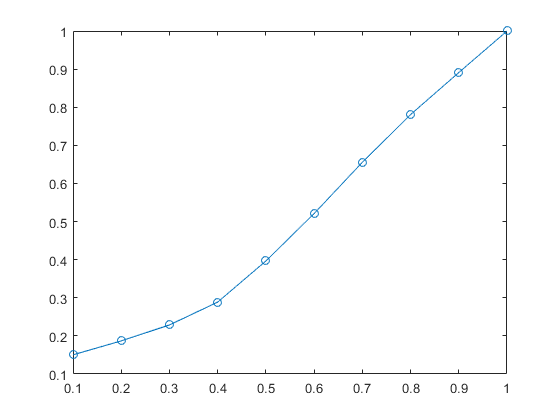


r = zeros(8,401);
for i = 1:10
    r(i,:) = meascale{i}.amplitude ./ meascale{10}.amplitude;
end
rmean = mean(r,2);
%veclut = [[0.1:0.1:1]' rmean]
%save('veclut','veclut')
clf
plot(0.1:0.1:1,rmean.^(1/2.2),'o-')

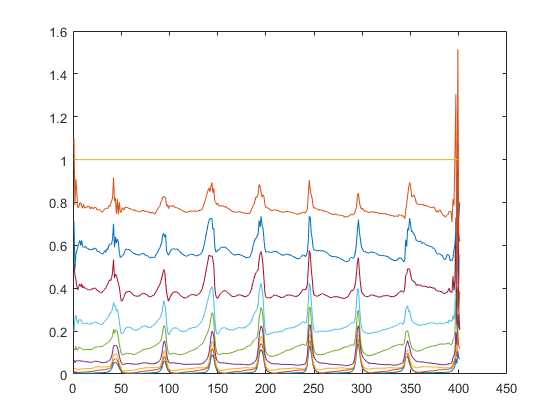



clf
plot(r')

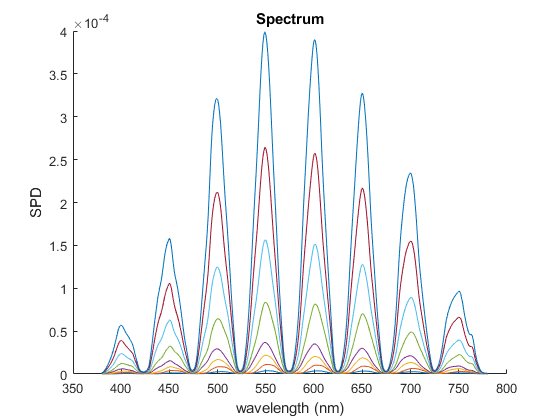


clf
hold on
for i = 1:8
    meascale{i}.plot
end

ratio_spec = zeros(10,401);
col_range  = [1:1024];
for i = 1:10
    rat = i/10;
    vec = LightSim.multiple_peaks(col_range) * rat;
    ol.setColumn1024(vec)
    mea = cs.measure;
    ratio_spec(i,:) = mea.amplitude;
end

Yxy =     0.1779    0.3883    0.4135


Yxy =     0.5577    0.3762    0.4105


Yxy =     1.2308    0.3752    0.4088


Yxy =     2.2982    0.3645    0.4021


Yxy =     5.4416    0.3732    0.4068


Yxy =    10.6310    0.3702    0.4059


Yxy =    18.4320    0.3720    0.4072


Yxy =    28.0120    0.3732    0.4081


Yxy =    37.8310    0.3735    0.4083


Yxy =    50.3100    0.3751    0.4086


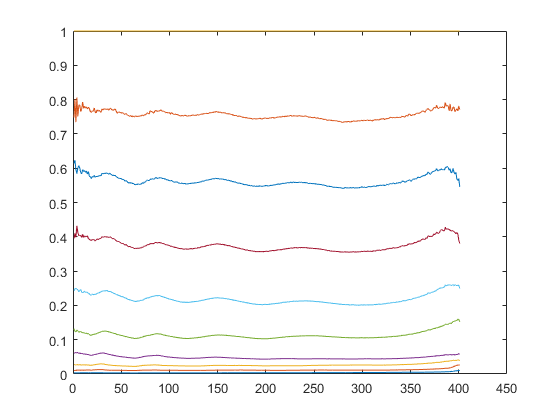

ratio_spec_normal = ratio_spec ./ repmat(ratio_spec(10,:),10,1);

clf
plot(ratio_spec_normal(:,:)')

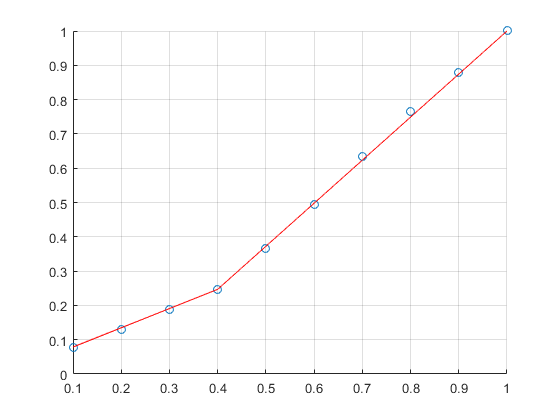


clf
hold on
x = 0.1:0.1:1;
y = mean(ratio_spec_normal(:,50:end-50)');
plot(x,y.^(1/2.2),'o')
%axis([0 1 0 1])
plot(x([1 4]),y([1 4]).^(1/2.2),'-r')
plot(x([4 10]),y([4 10]).^(1/2.2),'-r')
grid on

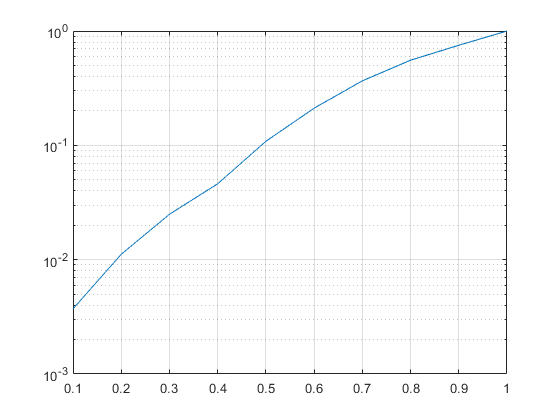


clf
semilogy(x,y)
grid on


slope = mean((y(2:end)-y(1:end-1))./(x(2:end)-x(1:end-1)))

slope = 1.1070

perc = y ./ x

perc =     0.0372    0.0557    0.0832    0.1153    0.2171    0.3521    0.5238    0.6947    0.8337    1.0000


Stability test

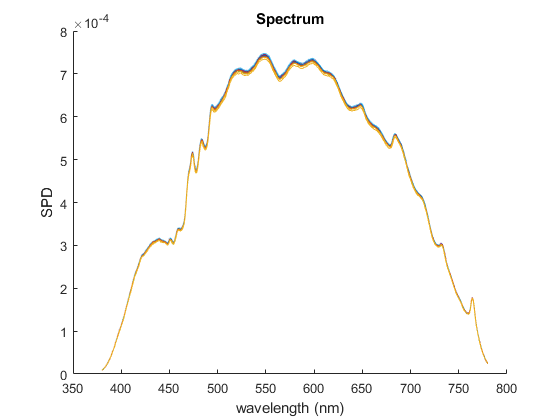

Yxy =    50.6010    0.3748    0.4081


Yxy =    50.6410    0.3749    0.4082


Yxy =    49.9700    0.3750    0.4081


Yxy =    50.7460    0.3749    0.4082


Yxy =    50.3480    0.3750    0.4082


Yxy =    50.8440    0.3748    0.4082


Yxy =    50.5830    0.3750    0.4082


Yxy =    50.5520    0.3750    0.4082


Yxy =    50.4400    0.3749    0.4081


Yxy =    50.2500    0.3750    0.4082



col_range  = [1:1024];
k = 500;
col_range  = [1:(k-1) (k+1):1024];

vec = LightSim.multiple_peaks(col_range);

clf
hold on
for i = 1:10
ol.setColumn1024(vec)
mea = cs.measure;
mea.plot
spec_stable(i,:) = mea.amplitude';
end

Try subtractive method


col_range  = [1:1024];

vec = LightSim.multiple_peaks(col_range);

ol.setColumn1024(vec)
mea = cs.measure;

Yxy =    50.0330    0.3751    0.4086


spec_measured0 = mea.amplitude';
lum = sum(spec_measured)

lum = 0.1894


k = 400

k = 400

col_range  = [1:(k-1) (k+1):1024];

vec = LightSim.multiple_peaks(col_range);

ol.setColumn1024(vec)
mea = cs.measure;

Yxy =    50.1020    0.3755    0.4081


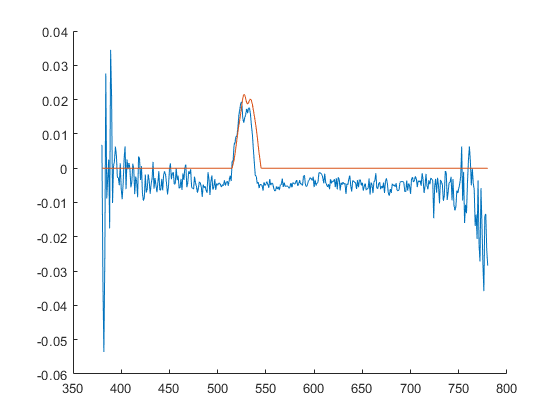

spec_measured1 = mea.amplitude';
ref_diff = (spec_measured0 - spec_measured1) ./ spec_measured0;

ref1 = spec_measured1 ./ spec_measured0;

%spec_predicted = ls.predict_vec_max(vec,spec_max);

%ratio_all = max(spec_measured) ./ max(spec_predicted)

clf
hold on
%plot(380:780,spec_measured0)
plot(380:780,ref_diff)
plot(380:780,ls.reflectance(k,:))

%plot(380:780,spec_measured0)
%plot(380:780,spec_measured1)
%plot(380:780,spec_predicted)
%legend('measured','predicted')

Check control accuracy


col_range  = [1:1024];

vec = LightSim.multiple_peaks(col_range) * 0.2;

ol.setColumn1024Gamma(vec)
mea = cs.measure;

Yxy =     8.2999    0.3716    0.4061


spec_measured = mea.amplitude';
lum = sum(spec_measured)

lum = 0.0313


spec_predicted = ls.predict_vec_max(vec,spec_max);

ratio_all = max(spec_measured) ./ max(spec_predicted)

ratio_all = 0.8253

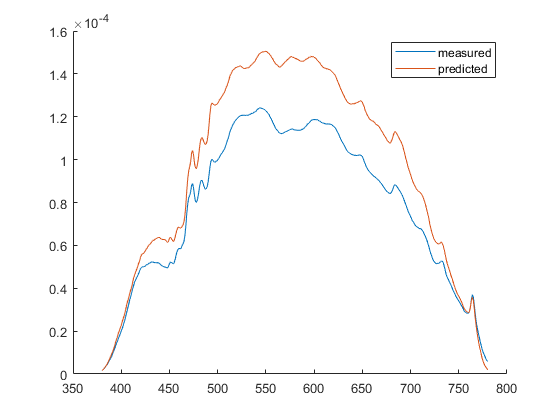


clf
hold on
plot(380:780,spec_measured)
plot(380:780,spec_predicted)
legend('measured','predicted')

light intensity changes over time -- full

Yxy =    51.0660    0.3752    0.4088


ratio_all = 0.7104

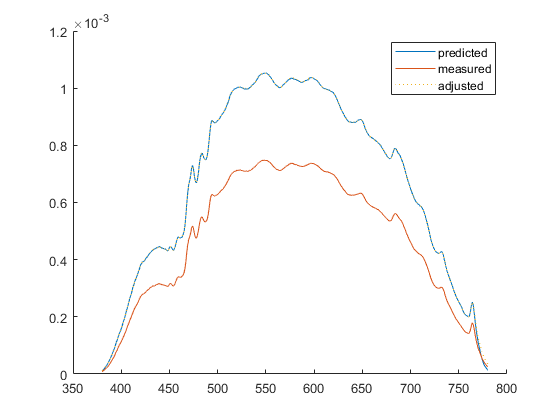

spec_predicted = ls.predict_vec_max(LightSim.multiple_peaks([1:1024]),spd_max);

mea = measure_white(ol,cs); 
spec_measured = mea.amplitude';

ratio_all = max(spec_measured) ./ max(spec_predicted)

clf
hold on
plot(380:780,spec_predicted)
plot(380:780,spec_measured)
plot(380:780,spec_measured/ratio_all,':')
legend('predicted','measured','adjusted')

Q: why prediction inaccurate?

A: compare prediction and measurement with 8 spikes

vec8_array = ls.vec_8_spikes;
vec8_sum = sum(vec8_array,1);

spec_predicted = ls.predict_by_filter(vec8_sum');

ol.setColumn1024(vec8_sum)
mea = cs.measure;

Yxy =    20.4810    0.3815    0.4082


spec_measured = mea.amplitude';

ratio_all = max(spec_measured) ./ max(spec_predicted)

ratio_all = 0.8495

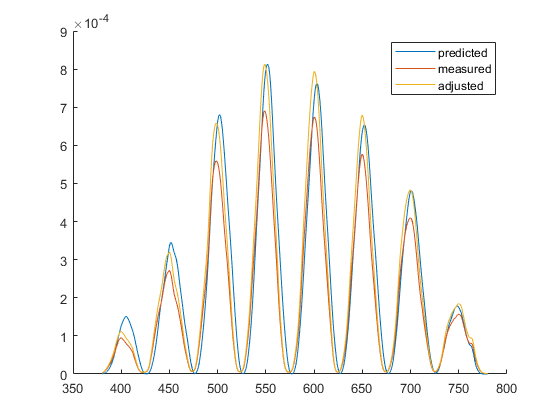


clf
hold on
plot(380:780,spec_predicted)
plot(380:780,spec_measured)
plot(380:780,spec_measured/ratio_all)
legend('predicted','measured','adjusted')

C: there is spectral shifting -- use max(spec) to get amplitude

function mea = measure_white (ol,cs)
c_range = 1:1024;
vec = LightSim.multiple_peaks(c_range);
ol.setColumn1024(vec)
mea = cs.measure;
end